% cat = importrobot('catalyst_matlab.urdf')
% show(cat)
close;
clear;
sawyer = importrobot('sawyer.urdf');
sawyer.DataFormat = 'column'

sawyer =   rigidBodyTree with properties:

     NumBodies: 20
        Bodies: {1×20 cell}
          Base: [1×1 rigidBody]
     BodyNames: {1×20 cell}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'column'


taskSpaceLimits = [0.25 0.5; -0.125 0.125; -0.15 0.1];
numJoints = 8; % Number of joints in robot


numSamples = 7;
[pathSegments, surface] = generateMembranePaths(numSamples, taskSpaceLimits);

'generateMembranePaths' is used in Manipulator Shape Tracing in MATLAB and Simulink.

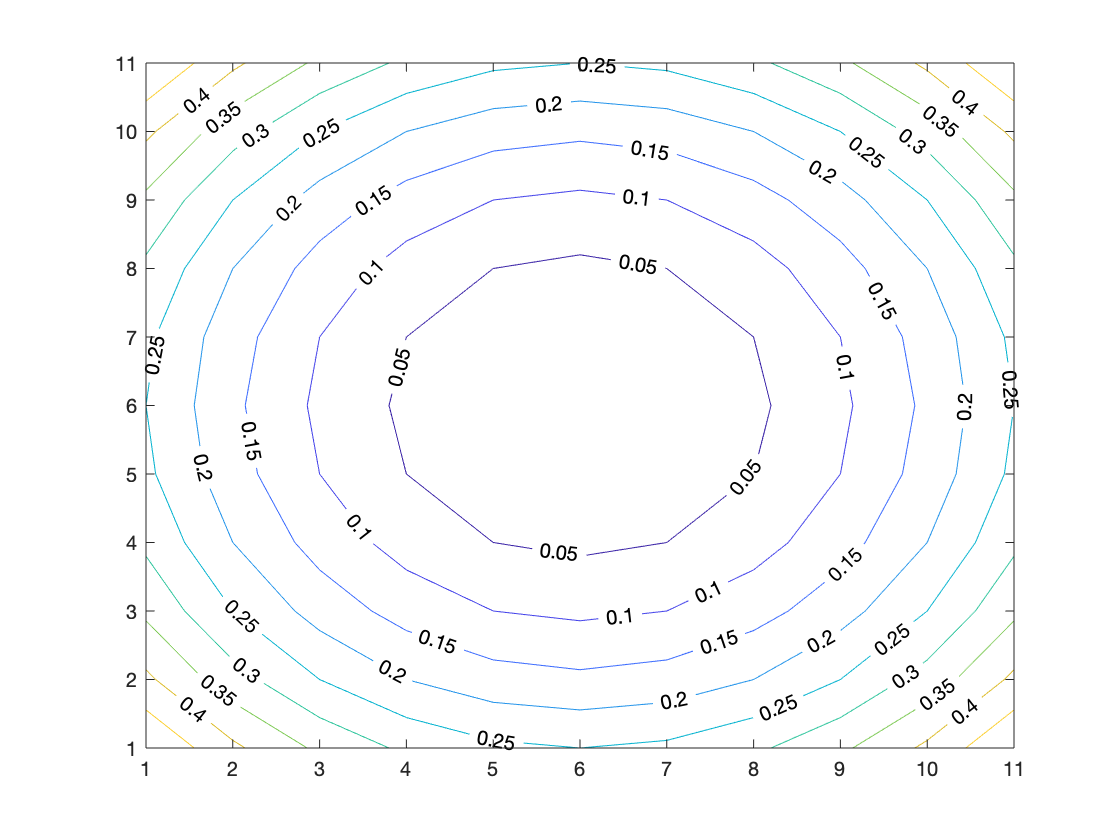


[X,Y] = meshgrid(-0.5:0.1:0.5, -0.5:0.1:0.5);
Z = (X).^2 + (Y).^2;
M= contour(Z, 'ShowText','on');
hold off;

% create a path based on this contour 
c_length = M(2,1);
z_height = M(1,1);
z_vec = ones(1, c_length) * z_height;
x_vec = M(1,2:1+ c_length)/20;
y_vec = M(2,2:1+ c_length)/20;
p1 = [x_vec', y_vec', z_vec'];
p2 = [x_vec', y_vec', 2 *z_vec'];
p3 = [x_vec', y_vec', 3 *z_vec'];
% put all the path pieces into a cell 
paths = {p1, p2, p3};
% plot3(M(1,2:1+ c_length), M(2,2:1+ c_length), z_vec);

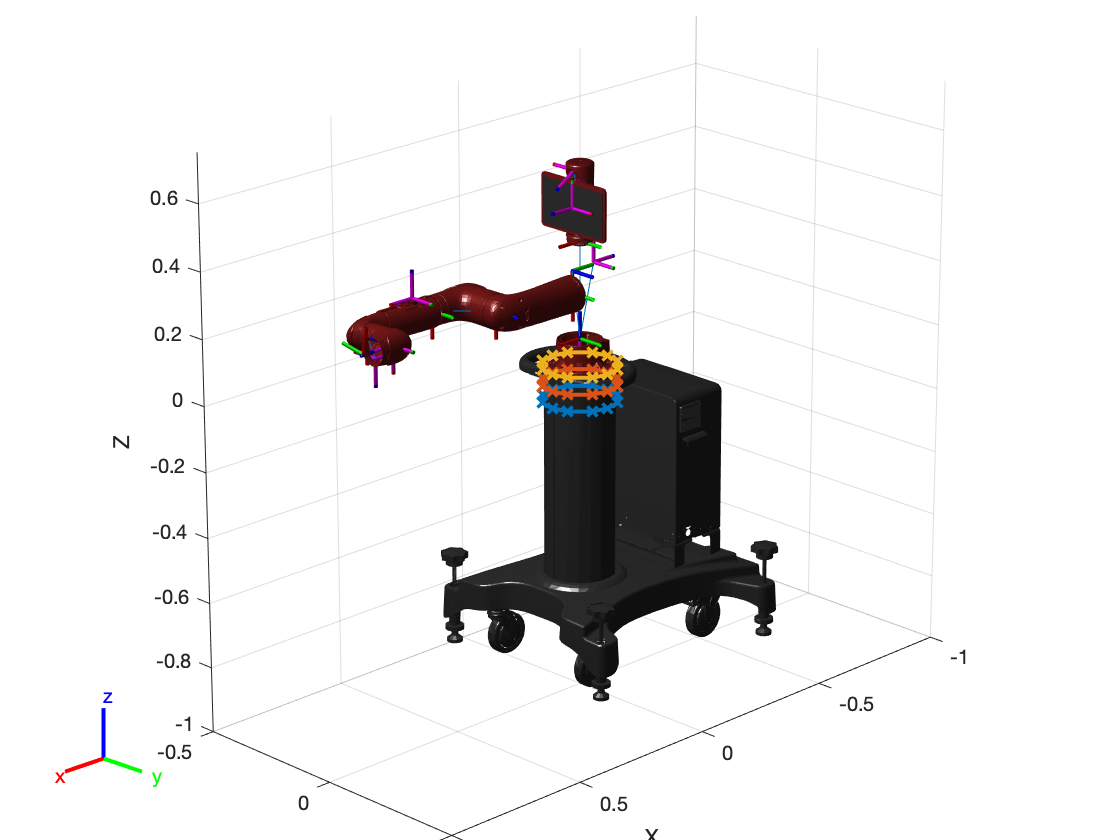

figure
show(sawyer);
hold on;
for i=1:numel(paths)
    segment = paths{i};
    plot3(segment(:,1),segment(:,2),segment(:,3),'x-','LineWidth', 2);
end

view(135,20)
axis([-1 1 -.5 .5 -1 .75])
hold off

ik = inverseKinematics('RigidBodyTree', sawyer);
initialGuess = sawyer.homeConfiguration;
weights = [1 1 1 1 1 1];
eeName = 'right_hand';

% Initialize the output matrix
numSamples = numel(x_vec);
jointPathSegmentMatrix = zeros(length(paths),numJoints,numSamples);

% Define the orientation so that the end effector is oriented down
sawyerOrientation = axang2rotm([0 1 0 pi]);

% Compute IK at each waypoint along each segment
for i = 1:length(paths)
    currentTaskSpaceSegment = paths{i};
    currentJointSegment = zeros(numJoints, length(currentTaskSpaceSegment));
    for j = 1:length(currentTaskSpaceSegment)
        pose = [sawyerOrientation currentTaskSpaceSegment(j,:)'; 0 0 0 1];
        currentJointSegment(:,j) = ik(eeName,pose,weights,initialGuess);
        initialGuess = currentJointSegment(:,j);
    end
    
    jointPathSegmentMatrix(i, :, :) = (currentJointSegment);
end



open_system("shapeTracingSawyer.slx")

sim("shapeTracingSawyer.slx")

xPositionsEE = reshape(eePosData.Data(1,:,:),1,size(eePosData.Data,3));
yPositionsEE = reshape(eePosData.Data(2,:,:),1,size(eePosData.Data,3));
zPositionsEE = reshape(eePosData.Data(3,:,:),1,size(eePosData.Data,3));

% Extract joint-space results
jointConfigurationData = reshape(jointPosData.Data, numJoints, size(eePosData.Data,3));

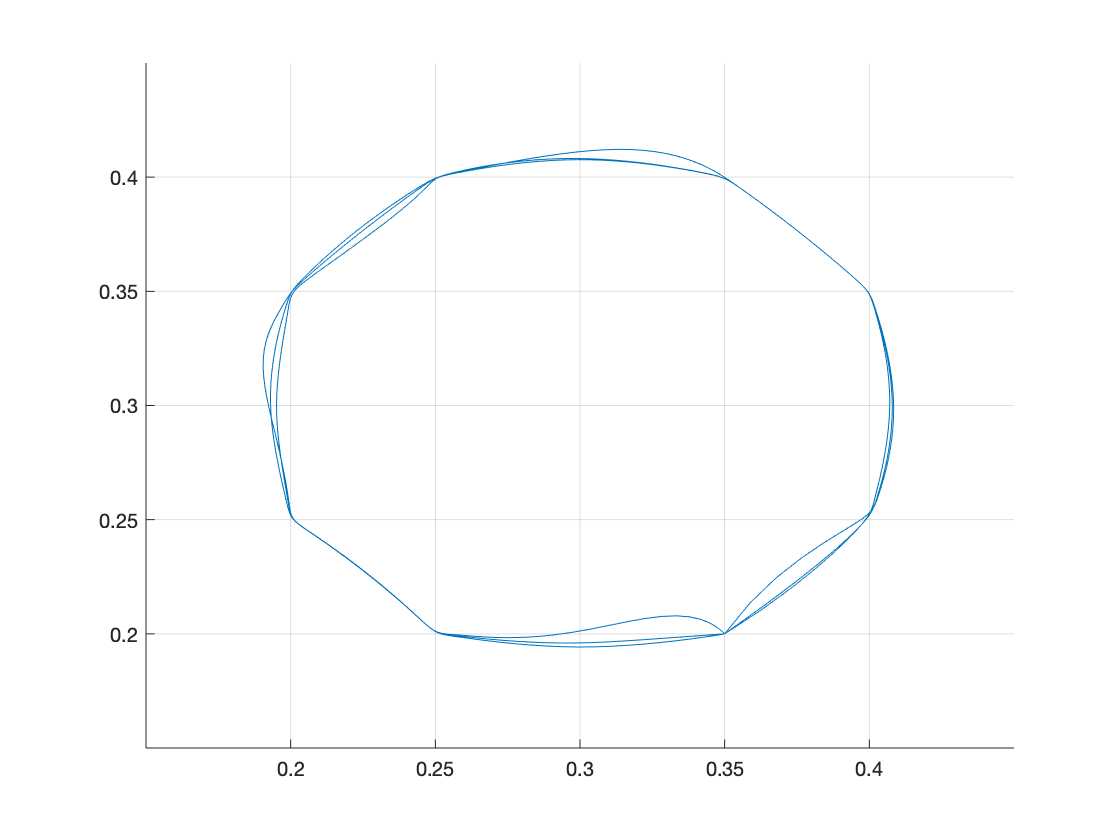

figure
% surf(surface{:},'FaceAlpha',0.3,'EdgeColor','none');
hold on
plot3(xPositionsEE,yPositionsEE,zPositionsEE)
grid on
hold off

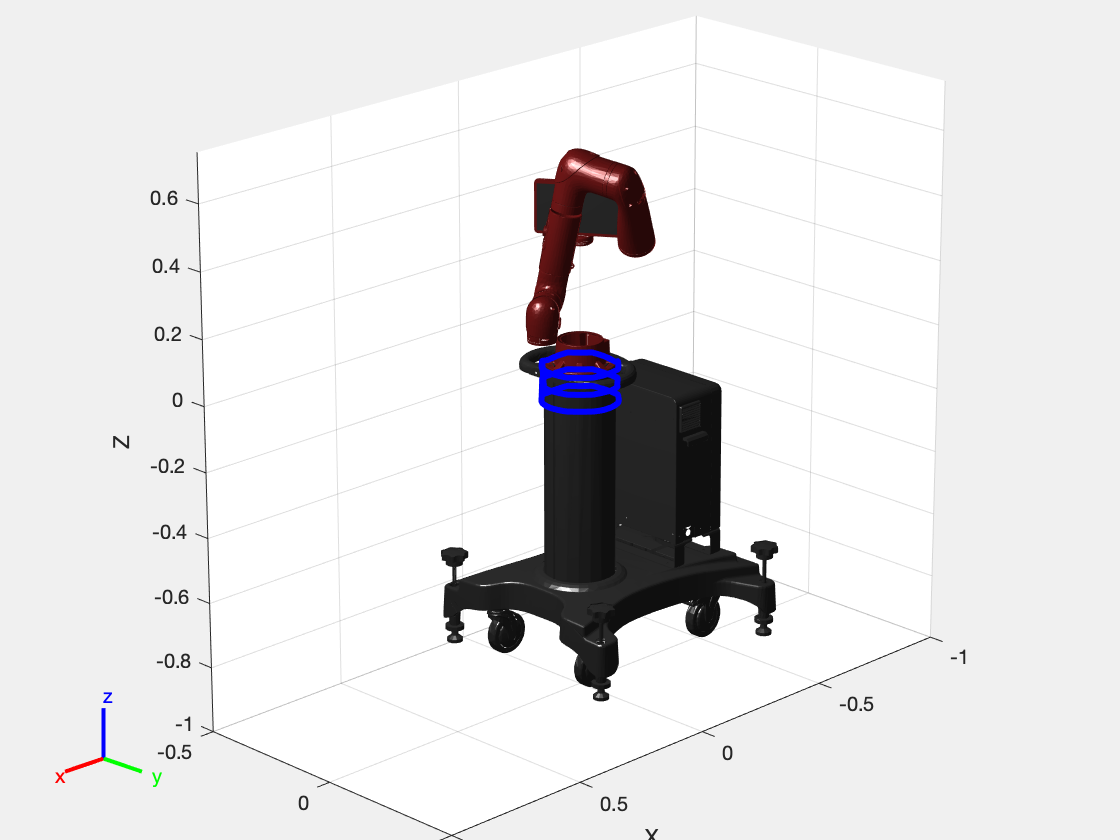

% For faster visualization, only display every few steps
vizStep = 5;

% Initialize a new figure window
figure
set(gcf,'Visible','on');

% Iterate through all joint configurations and end-effectort positions
for i = 1:vizStep:length(xPositionsEE)
    show(sawyer, jointConfigurationData(:,i),'Frames','off','PreservePlot',false);
    hold on
    plot3(xPositionsEE(1:i),yPositionsEE(1:i),zPositionsEE(1:i),'b','LineWidth',3)
    
    view(135,20)
    axis([-1 1 -.5 .5 -1 .75])
    
    drawnow
end
hold off